## Plotting EISCAT Data from a hdf5 file

This is an example of how to:

- Read in data from an EISCAT hdf5 data file such as those produced by GUISDAP.

- plot the data as a 3D grid plot

- extract data for a specific time and plot an altitude plot

- convert the data from range, azimuth and elevation to geographic latitude and longitude

**The codes below should work on the UNIS machines.**

## Pre-requisit functions

The program uses pre-written function called ***load_param_hdf5_new ***and ***loc2gg***. These can be found (along with supplemental programs it needs to run) on the UNIS machines inside the GUISDAP folder.  To use them you need to add the path to these functions so matlab can run them.  This is done using the **'addpath'** command (as shown in section 1 below where the path points to the guisdap software on the UNIS machines).  

**You will need to have this 'addpath' line in every program you write which requires the pre-written functions.**

## 1. Read in the EISCAT hdf5 data file

NOTE:  If you run this on your own machine you will need to copy the files located in the folder shown in the 'addpath' line below onto your own computer in the relevant directory.  These can be found on the UNIS computers.

NOTE:  An example hdf5 file can be found on the canvas page if you wish to test your code.

clear all
% add the data path to the function and supporting programs
addpath 'W:\COURSE MTR & DATA StudentsReadOnly\AGF\AGF_304_software\guisdap9_2\anal\'

% remember to change the data path to point to correct location of EISCAT data file
[Time,locn,par2D,par1D,rpar2D,err2D,errs2d]=load_param_hdf5_new('W:\COURSE MTR & DATA StudentsReadOnly\AGF\AGF304_data\test_data\EISCAT\EISCAT_2019-11-20_folke_64@42mb.hdf5');


### Assign the data to named arrays

When working with large datasets it is useful to seperate them out into arrays with sensible names.

% read the basic parameters into some usefully named arrays
[y,m,d,h,mn,s]=datevec(Time(1,:)); % use the datevec function to put the time into something useable (year, monthm day, hour, min, sec)
ut_time=h+mn/60.; % time in UT of the data
alt=par2D(:,:,2); % altitude
ne=par2D(:,:,3); % electron density
te=par2D(:,:,4); % electron temperature
ti=par2D(:,:,5); % ion temperature
azm=par1D(:,1); % azimuth angle of the dish
eln=par1D(:,2); % elevation angle of the dish
rng=par2D(:,:,1); % range
pp_alt=rpar2D(:,:,2); % altitude for the 'raw electron density data' (power profile data)
pp_ne=rpar2D(:,:,3); % 'raw electron density / backscatter power' (power profile data)

% read in the error values if needed
ne_err=err2D(:,:,1);

## 2. Plotting the data in a grid plot

There are some nice functions in matlab which allow you to force the X-axis to UT time.  An example is shown below (*datetick*)

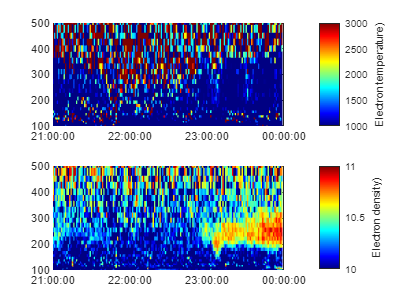

 % set the data range for the plot manually using datenum
 % this allows you to use year, month, day, hour, min, sec to specify a time range for yout plotting axis

n1 = datenum([2019 11 20 21 00 00]); 
n2 = datenum([2019 11 21 00 00 00]);

xLimits=[n1 n2];

% now use pcolor (or imagesc) to plot the data (along with the other
% plotting functions you have learnt)
yLimits=[100 500];
colormap jet;

subplot(2,1,1);
%use datenum again to force the plotting axis to have the time in UT
pcolor(datenum([y(:),m(:),d(:),h(:),mn(:),s(:)]),alt,te),shading flat;
% give the limits of the colourbar
caxis([1000 3000]);
% % Add colorbar to the right of the plot
colorbar;
set(get(colorbar,'label'),'FontSize', 8,'string','Electron temperature)')
xlim(xLimits);
 ylim(yLimits) ;
datetick('x',13,'keeplimits'); % force the ticks on the x-axis to use the UT format

subplot(2,1,2);
%use datenum again to force the plotting axis to have the time in UT
pcolor(datenum([y(:),m(:),d(:),h(:),mn(:),s(:)]),alt,log10(ne));
shading flat;
% give the limits of the colourbar
caxis([10 11]);
% % Add colorbar to the right of the plot
colorbar;
set(get(colorbar,'label'),'FontSize', 8,'string','Electron density)')
xlim(xLimits);
 ylim(yLimits) ;
datetick('x',13,'keeplimits'); % force the ticks on the x-axis to use the UT format

## 3. Extracting the data and plotting an altitude profile plot

In some occasions you would like to look at an altitude plot and the associated errors.

(This part of the code is obviously reliant on the data being read in using part 2 above.

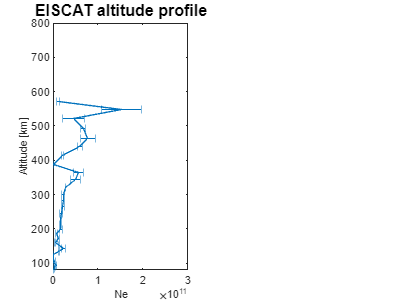

%chose the time of interest
% there are various ways to do this.  Here I am just using the array index number
% which corresponds to that time.
time_for_plot=21.2 ;
nm= find(ut_time==time_for_plot) ;
% pick out the data from that time period and plot an altitude profile,
% including error bars
yLimits=[80 800];
subplot(1,2,1);
 errorbar(ne(:,nm),alt(:,nm),ne_err(:,nm),'horizontal');
xlim([0 3e11]);
 ylim(yLimits) ;
 xlabel('Ne','FontSize', 8,'FontName','Arial')
 ylabel('Altitude [km]','FontSize', 8,'FontName','Arial')
 plot_title=['EISCAT altitude profile'];
 title(plot_title,'FontSize', 12,'FontName','Arial');

## 4. Converting from range, azimuth and elevation to latitude and longitude

The default program provided by EISCAT to read in the HDF5 data reads in the radar co-oridnates.  The script below converts the radar co-oridnates to latitude and longitude using a script also provided within GUISDAP. (These can then be trasnformed to geomagnetic latitude and longitude using a magnetic field model of your choice - generally the AACGM model is used.  This is outside the scope of this module). 

% add the data path to the function and supporting programs
%addpath 'W:\COURSE MTR & DATA StudentsReadOnly\AGF\AGF_304_software\guisdap9_2\anal\'
% use a loop to run convert all data points from (range, azimuth and
% elevation) to (latitude (lat) and longitude (lon))
for j= 1:length(rng(:,1));
     for jj=1:length(rng(1,:)); 
   dd=loc2gg(locn,[eln(jj), azm(jj), rng(j,jj)]);
   lat(j,jj)=dd(1);
   lon(j,jj)=dd(2);
   end;
 end;
 % the data can now be plotted using similar code to that in section 2.